# Removing Background in an Image

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

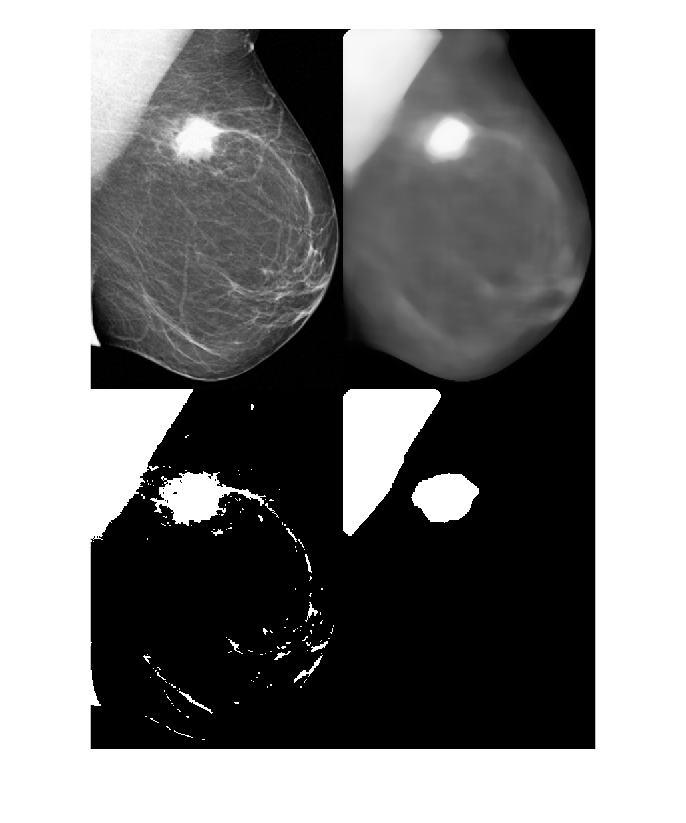

tumor = readmatrix("./images/tumorReducedSize.csv", OutputType="uint8");
tumorBW = imbinarize(tumor);
filterSize = [15 15];
tumorMed = medfilt2(tumor, filterSize); 
tumorMedBW = imbinarize(tumorMed);
montage({tumor, tumorBW; tumorMed, tumorMedBW}, "Size", [2 2])

## Task 1

To perform background subtraction, you must first define a neighborhood. You can use the `ones` function to create a square neighborhood

`nhood` `=` `ones``(``n``)``;`

nhood = ones(30);

## Task 2

The `imtophat` function removes uneven background illumination when the background is darker than the foreground.

`I2` `=` `imtophat``(``I``,``nhood``)``;`

This does both the background estimation and subtraction for you. You do not need to do these steps separately

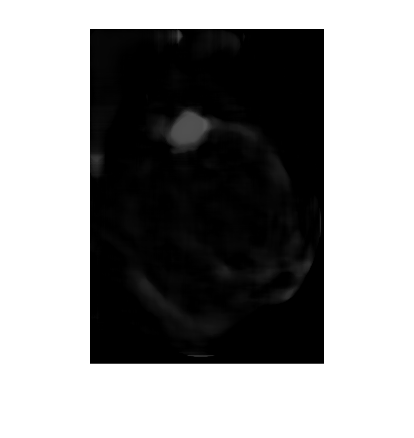

tumorTopHat = imtophat(tumorMed, nhood);
imshow(tumorTopHat)

## Task 3

The skin that shows up in the upper left has been removed. Now let's try binarizing the tumor.

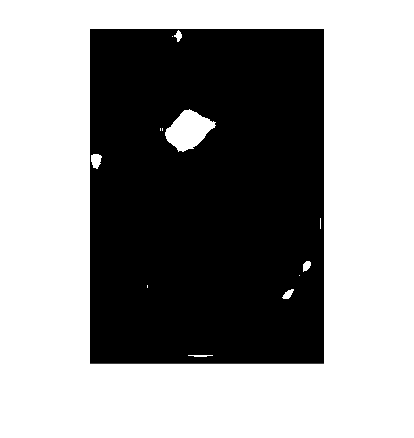

tumorBW = imbinarize(tumorTopHat);
imshow(tumorBW)